Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

clear all
%close all
clc

f1 = @(x) (6*x-2).^2.*sin(12*x-4);

xx = linspace(0,1,100)';
yy = f1(xx);

x1 = lhsdesign(500,1);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.8);

ma = means.const(2)+means.linear(6)

ma =   const with properties:

         meanz: {[1×1 means.const]  [1×1 means.linear]}
        coeffs: {[2]  [6]}
    operations: {'+'}


a = kernels.Matern52(1,0.2)*kernels.EQ(1,0.4).periodic(1,2) + kernels.RQ(0.1,0.3);

a.signn = 0.5;

Z = VGP(ma,a,linspace(0,1,5)');

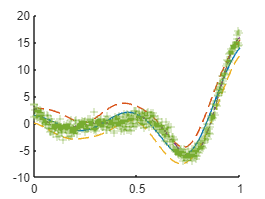

Z1 = Z.condition(x1,y1);

[ys,sig] = Z1.eval(xx);

figure
hold on
plot(xx,ys)
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')

tic
[Z2,LL] = Z1.train(1);
toc

Elapsed time is 1.904809 seconds.


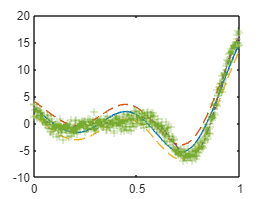

[ys,sig] = Z2.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')


for i = 1:5
    xn = bads(@(x) Z2.newXuDiff(x),rand(),0,1);
    Z2 = Z2.addInducingPoints(xn);
end

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2      -0.0320185               1                              Uncertainty test
     0           3       -0.962062               1            Initial mesh      
     1           4       -0.962062             0.5             Refine grid      Train (failed)
     2           7       -0.974472             0.5    Incremental search (ES-wcm)      
     2           8       -0.974472            0.25             Refine grid      
     3           9        -0.98669            0.25    Incremental search (ES-wcm)      
     3          10       -0.987631            0.25    Incremental search (ES-ell)      
     3          11       -0.987932            0.25    Incremental search (ES-wcm)      
     3          13       -0.987932           0.125             Refine grid      
     4          15       -0.992605           0.125    Incremental se

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.596056               1                              Uncertainty test
     0           3       -0.596056               1            Initial mesh      
     1           4       -0.596056             0.5             Refine grid      Train (failed)
     2           6       -0.640654             0.5    Incremental search (ES-wcm)      
     2           7       -0.640659             0.5    Incremental search (ES-wcm)      
     2           9       -0.640659            0.25             Refine grid      
     3          11       -0.640659            0.25    Incremental search (ES-ell)      
     3          14       -0.640659           0.125             Refine grid      Train
     4          19       -0.640659          0.0625             Refine grid      
     5          20        -0.64066          0.0625    Incremental sear

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2       -0.430653               1                              Uncertainty test
     0           3       -0.430653               1            Initial mesh      
     1           4       -0.430653             0.5             Refine grid      Train (failed)
     2           5       -0.478922             0.5    Incremental search (ES-wcm)      
     2           7       -0.489955             0.5    Incremental search (ES-ell)      
     2           8       -0.489955            0.25             Refine grid      
     3           9       -0.490131            0.25    Incremental search (ES-wcm)      
     3          10       -0.490133            0.25    Incremental search (ES-wcm)      
     3          11       -0.490134            0.25    Incremental search (ES-wcm)      
     3          13       -0.490134           0.125           

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2      -0.0059507               1                              Uncertainty test
     0           3       -0.036541               1            Initial mesh      
     1           4       -0.036541             0.5             Refine grid      Train (failed)
     2           9       -0.036541            0.25             Refine grid      
     3          14       -0.036541           0.125             Refine grid      Train
     4          15      -0.0372916           0.125    Incremental search (ES-ell)      
     4          16      -0.0372927           0.125    Incremental search (ES-wcm)      
     4          19      -0.0372927         0.03125             Refine grid      
     5          20       -0.037404         0.03125    Incremental search (ES-ell)      

Optimization terminated: change in the function value less than OPTIO

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2     -0.00487392               1                              Uncertainty test
     0           3     -0.00487392               1            Initial mesh      
     1           4     -0.00487392             0.5             Refine grid      Train (failed)
     2           9     -0.00487392            0.25             Refine grid      
     3          11     -0.00502102            0.25    Incremental search (ES-wcm)      
     3          14     -0.00502102           0.125             Refine grid      Train
     4          19     -0.00502102         0.03125             Refine grid      

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -0.00502102.



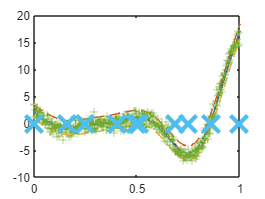


[ys,sig] = Z2.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')
plot(Z2.Xu,0*Z2.Xu,'x','MarkerSize',18,'LineWidth',3)

tic
[Z3,LL] = Z2.train(1);
toc

Elapsed time is 2.026030 seconds.


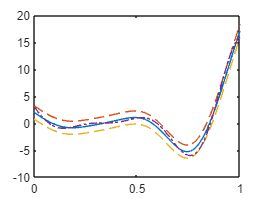


[ys,sig] = Z3.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')